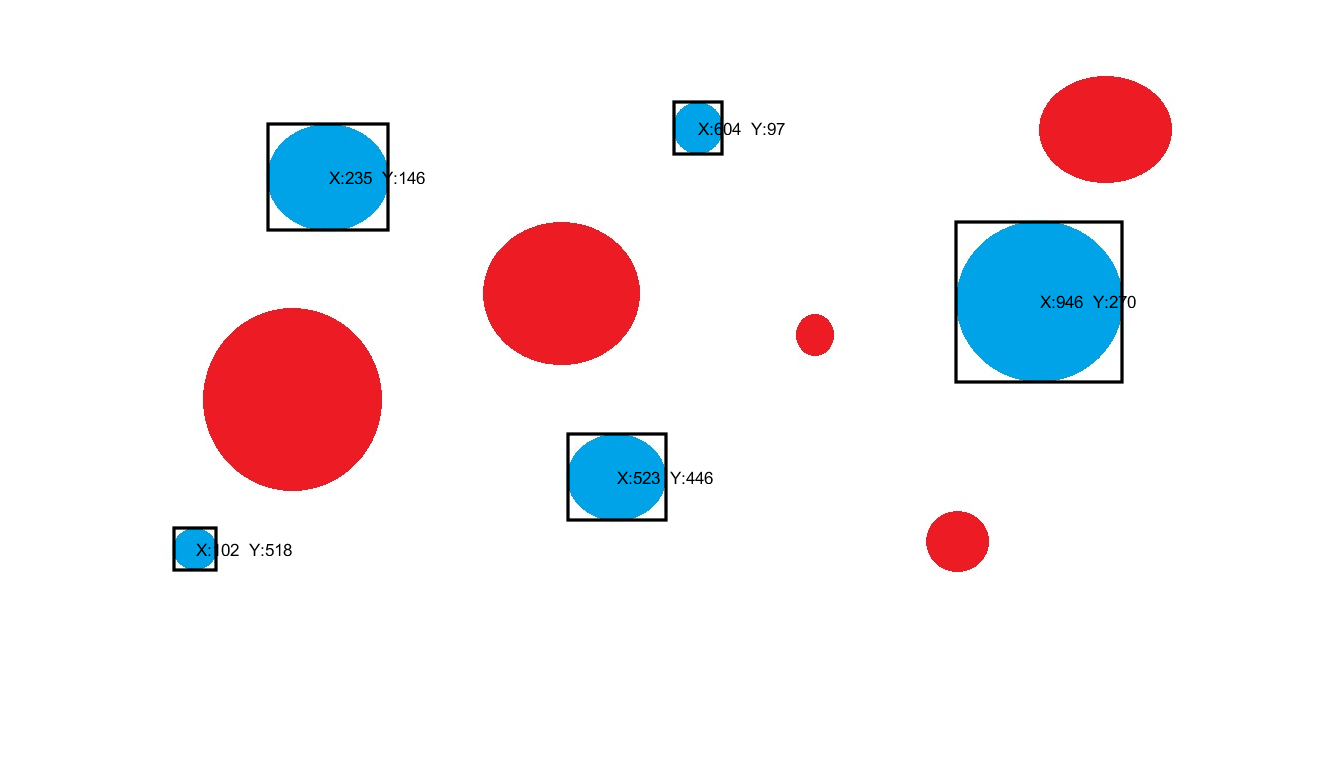

clear
close
clc

a=imread('C:\Users\Admin\Desktop\circles.jpg');

r=a(:,:,1);
g=a(:,:,2);
b=a(:,:,3);

grayscale=rgb2gray(a);

c=b-grayscale;
c=im2bw(c,0.3);

props=regionprops(c,'BoundingBox','Centroid');
imshow(a);
hold on;
for i=1:length(props)
    pos=props(i).BoundingBox;
    rectangle('Position',pos,'LineWidth',2);
    cent=round(props(i).Centroid);
    text(cent(1),cent(2),strcat("X:",num2str(cent(1)),"  Y:",num2str(cent(2))));
end
hold off;